# Pętla PLL

% code
fs = 1000e3; fpilot = 19e3; tmax = 1;
t = [0:1/fs:tmax-1/fs];
signal = sin(2*pi*fpilot*t);

effect = PLL(signal, fpilot, fs);

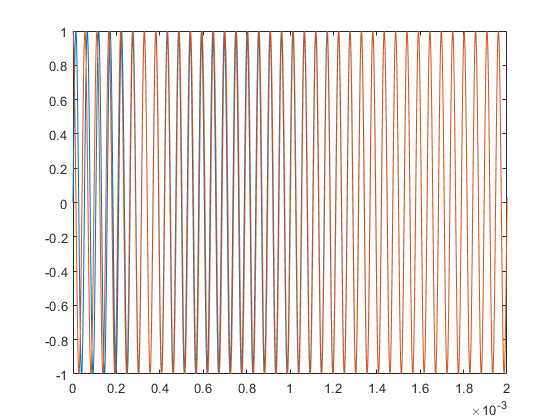

figure
plot(t, signal, t, effect)
xlim([0 2e-3])

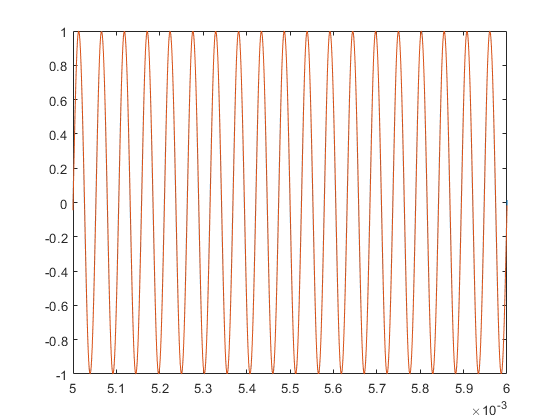


figure 
plot(t, signal, t, effect)
xlim([5e-3 6e-3])

function c = PLL(p, fpilot, fs)
    % Petla PLL z filtrem typu IIR do odtworzenia częstotliwości i fazy pilota [7]
    % i na tej podstawie sygnałów nośnych: symboli c1, stereo c38 i danych RDS c57
    % global fpilot; global fs;
    
    freq = 2*pi*fpilot/fs;
    theta = zeros(1,length(p)+1);
    alpha = 1e-2;
    beta = alpha^2/4;
    for n = 1 : length(p)
        perr = -p(n)*sin(theta(n));
        theta(n+1) = theta(n) + freq + alpha*perr;
        freq = freq + beta*perr;
    end
    c(:,1) = cos(theta(1:end-1));
end